# **4 Fluid Kinematics**

## **4.2 Flow Patterns and visualization.**

***(Fluid Mechanics, Cengel, 3rth)***

It's better  to explaing using examples. Process to solve is explained in book. So, let's get straight into it.

## **Steady Flow **(It does not depends on time)

Let a 2-D velocity vector field be: 


$$\overrightarrow{V}(x,y,t) = ui + vj \\

\overrightarrow{V}(x,y,t) = (0.5 + 0.8x)i  + (1.5-0.8y)j
$$


By solving the equation, solution is: 


$$ y= \frac{C}{0.8(0.5+0.8x)} + 1.875,\  C = constant
$$


To represent the fluid pattern, it takes to give form to the general expression of function $z = f(x,y,t): 
$


$$                      z = f(x,y,t) =  y- \frac{C}{0.8(0.5+0.8x)} - 1.875 = 0
$$


### Represent fluid in a 2-D plane. For differents values of constant  C

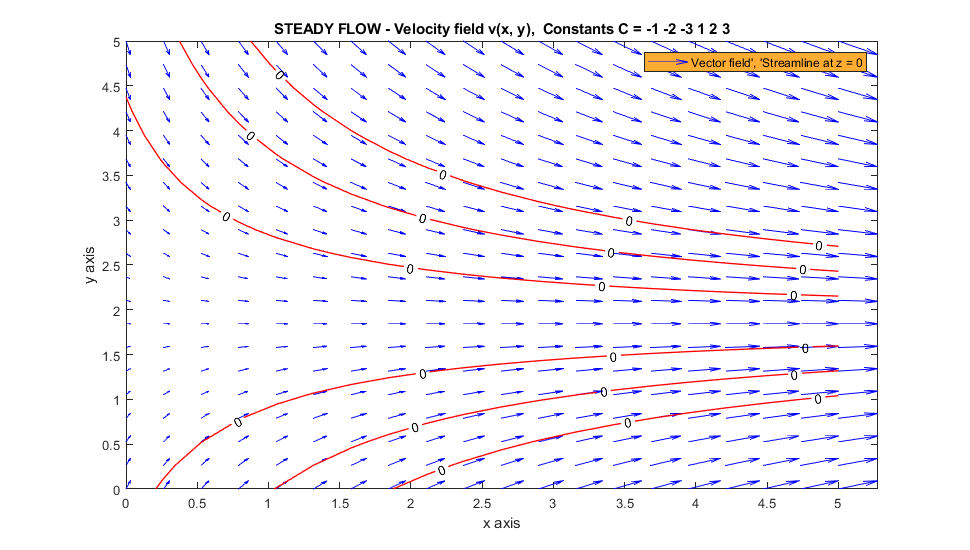


clear, clc, close all;

% define X-Y plane, wih  a density of arrows of 25
n = 20; % density of points
X = linspace(0,5,n);
Y = linspace(0,5,n);
t = linspace(0,5,100);

% transforms the domain specified by vectors X and Y into arrays x and y
[x, y] = meshgrid(X, Y);

% Constant
C = [-1, -2, -3, 1, 2, 3];

% Z level to be draw
z_lev = 0;

%%
% figh = figure(1);
figh = figure;
figh.Position = [10 10 970 550]; % Pizel for video

% Because is STEADY FLOW, the flow does not change on time
    
%%% Plot Vectorial Field %%%

% Vectorial components of velocity vectorial field
u = 0.5 + 0.8*x;                 % u: Velocity field component in x axis
v = 1.5 - 0.8*y;                 % v: Velocity field component in y axis

% 2D arrows field using u and v (color is in normalized RGB)
q = quiver(x, y, u, v, 'color',[0 0 1]);

hold on;

%%% Plot STREAMLINE %%%

for Cv = C
    % give form the function z:
    A = y - 1.875;
    B = 0.8*(0.5 +0.8*x);
    z = A.*B - Cv;   %  z = f(x,y,t) = 0

    % plot, z must be represented on a plane parallel to x-y plane:
    [M,a] = contour(x,y,z);
    a.LineWidth = 1;
    a.LevelList = z_lev;  % Draws level. z = f(x,y,t) = y*x^(t) - C = level
    a.LineColor = 'r';    % Color red
    a.ShowText = 'on';    % Show current level on plot

end

% Properties of axes
xlabel('x axis', 'fontsize', 11);
ylabel('y axis', 'fontsize', 11);
% Title  
title( "STEADY FLOW - Velocity field v(x, y),  Constants C = " + strjoin(string(C)));
legend({"Vector field', 'Streamline at z = " +  strjoin(string(z_lev))}, 'Color', '#ffac33')

hold off;

exportgraphics(figh,'SteadyFlow_4C.png')


disp('DONE!')

DONE!


## **Unsteady Flow **(It does depends on time)

Let a 2-D velocity vector field be: 


$$\overrightarrow{V}(x,y,t) = ui + vj \\

\overrightarrow{V}(x,y,t) = xi + (-y*t)j
$$


**It is spacial 2-D, and 1-D in time.*

By solving the equation, solution is: 


$$ y= C*x^{-t},\  C = constant
$$


To represent the fluid pattern, it takes to give form to the general expression of function $z = f(x,y,t): 
$


$$                      z = f(x,y,t) = y*x^{t} - C = 0   
$$


To plot the function, $z = f(x,y,t)
$ must be represented on a plane parallel to x-y plane. So:


$$                      z = f(x,y,t) = y*x^{t} - C = level,  \\
$$


### Represent fluid in a 2-D plane. For a constant C = 2. *(Check video generated) :*

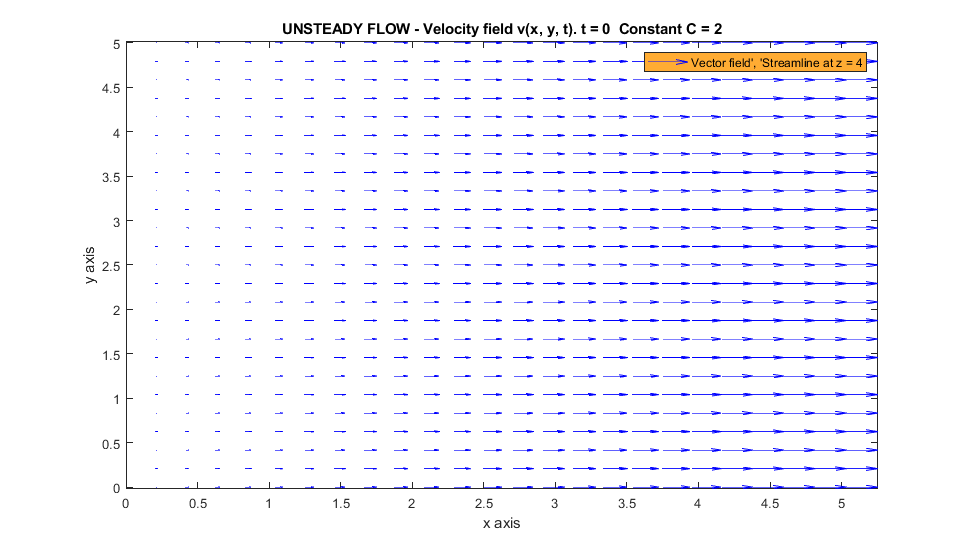


clear, clc, close all;

% define X-Y plane, wih  a density of arrows of 25
X = linspace(0,5,25);
Y = linspace(0,5,25);
t = linspace(0,5,100);

% transforms the domain specified by vectors X and Y into arrays x and y
[x, y] = meshgrid(X, Y);

% Constant
C = 2;

% Z level to be draw
z_lev = 4;

% figh = figure(1);
figh = figure;
figh.Position = [10 10 970 550]; % Pizel for video

% Because is UNSTEADY FLOW, the flow must change on time
for k = 1:length(t)              % time goes through
    
    %Current time step
    t_k = t(k);
    
    %%% PLOT VECTORIAL FIELD %%%
    
    % Vectorial components of velocity vectorial field
    u = x;                       % u: Velocity field component in x axis
    v = -y.*t_k;                 % v: Velocity field component in y axis
    
    % 2D arrows field using u and v (color is in normalized RGB)
    q = quiver(x, y, u, v, 'color',[0 0 1]);
    
    hold on;
    
    %%% PLOT STREAMLINE %%%
    
    % give form the function z:
    z = y.*(x.^t_k) - C;   %  z = f(x,y,t) = y*x^(t) - C = 0
    
    % plot, z must be represented on a plane parallel to x-y plane:
    [M,a] = contour(x,y,z);
    a.LineWidth = 1;
    a.LevelList = z_lev;  % Draws level. z = f(x,y,t) = y*x^(t) - C = level
    a.LineColor = 'r';    % Color red
    a.ShowText = 'on';    % Show current level on plot
    
    % Properties of axes
    xlabel('x axis', 'fontsize', 11);
    ylabel('y axis', 'fontsize', 11);
    % Title updating time
    title(['UNSTEADY FLOW - Velocity field v(x, y, t). t = ',num2str(t_k), '  Constant C = 2'])
    legend({"Vector field', 'Streamline at z = " +  strjoin(string(z_lev))}, 'Color', '#ffac33')
    
    hold off;
    
    pause(0.5)            % Stop 0.5s on every step
    movieVector(k) = getframe(figh, [10 10 960 540]); % Pixels in video
    
end

%Create a VideoWriter object and set properties
myWriter = VideoWriter('UnsteadyFlow_1C', 'MPEG-4');
myWriter.FrameRate = 20;

%Open the VideoWriter object, write the movie, and close the file
open(myWriter);
writeVideo(myWriter, movieVector);
close(myWriter);

exportgraphics(figh,'UnsteadyFlow_1C.png')


disp('DONE!')

DONE!


### Represent fluid in a 2-D plane. For constants C = 2, 5 and 8. *(Check video generated):*

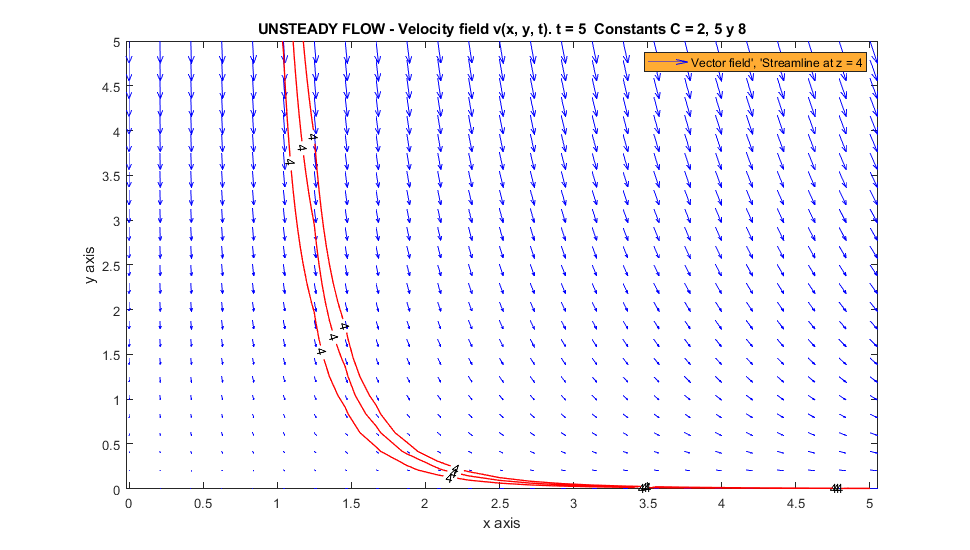


clear, clc, close all;

% define X-Y plane, wih  a density of arrows of 25
X = linspace(0,5,25);
Y = linspace(0,5,25);
t = linspace(0,5,100);

% transforms the domain specified by vectors X and Y into arrays x and y
[x, y] = meshgrid(X, Y);

% Constant
C = [2, 5, 8];

% Z level to be draw
z_lev = 4;

% figh = figure(1);
figh = figure;
figh.Position = [10 10 970 550]; % Pizel for video

% Because is UNSTEADY FLOW, the flow must change on time
for k = 1:length(t)              % time goes through
    
    %Current time step
    t_k = t(k);
    
    %%% PLOT VECTORIAL FIELD %%%
    
    % Vectorial components of velocity vectorial field
    u = x;                       % u: Velocity field component in x axis
    v = -y.*t_k;                 % v: Velocity field component in y axis
    
    % 2D arrows field using u and v (color is in normalized RGB)
    q = quiver(x, y, u, v, 'color',[0 0 1]);
    
    hold on;
    
    %%% PLOT STREAMLINE %%%
    
    for Cv = C
        % give form the function z:
        z = y.*(x.^t_k) - Cv;   %  z = f(x,y,t) = y*x^(t) - C = 0
        
        % plot, z must be represented on a plane parallel to x-y plane:
        [M,a] = contour(x,y,z);
        a.LineWidth = 1;
        a.LevelList = z_lev;  % Draws level. z = f(x,y,t) = y*x^(t) - C = level
        a.LineColor = 'r';    % Color red
        a.ShowText = 'on';    % Show current level on plot
        
    end
    
    % Properties of axes
    xlabel('x axis', 'fontsize', 11);
    ylabel('y axis', 'fontsize', 11);
    % Title updating time
    title(['UNSTEADY FLOW - Velocity field v(x, y, t). t = ',num2str(t_k), '  Constants C = 2, 5 y 8'])
    legend({"Vector field', 'Streamline at z = " +  strjoin(string(z_lev))}, 'Color', '#ffac33')
    
    hold off;
    
    pause(0.5)            % Stop 0.5s on every step
    movieVector(k) = getframe(figh, [10 10 960 540]);   % Pixels in video
    
end

%Create a VideoWriter object and set properties
myWriter = VideoWriter('UnsteadyFlow_3C', 'MPEG-4');
myWriter.FrameRate = 20;

%Open the VideoWriter object, write the movie, and close the file
open(myWriter);
writeVideo(myWriter, movieVector);
close(myWriter);

exportgraphics(figh,'UnsteadyFlow_3C.png')


disp('DONE!')

DONE!
